clc;
clear;
%[signal, sample_rate] = audioread('A0.wav'); %Reading the audio signal

fs = 360;
x = load('100m (0).mat')

x = struct with fields:
    val: [1×3600 double]


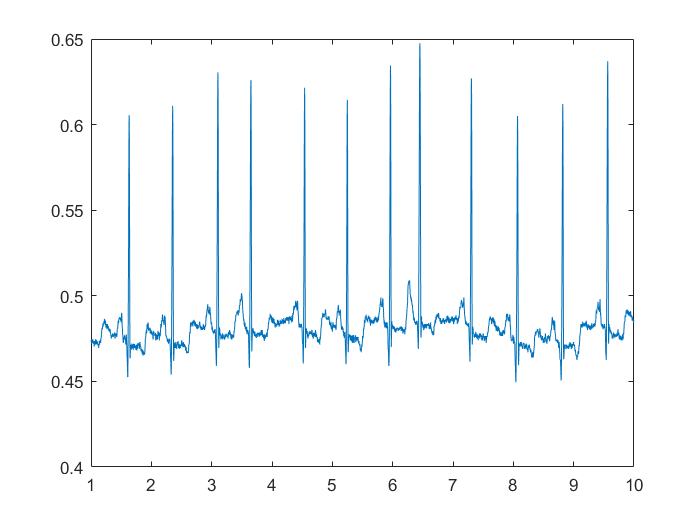

y = x.val/2000;
t = 3600/360;
sample_rate = 1/fs;

plot(linspace(1, t, 3600),y(1:t*fs))


%fs - 1/t sample rate
%y - samples/signal


%Detect R peaks
% r_peak_indices = detect_r_peaks_in_audio(signal, sample_rate);
% 
% % Plot the R peaks on top of the audio signal
% figure;
% plot(signal, 'k');
% hold on;
% plot(r_peak_indices, signal(r_peak_indices), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
% xlabel('Sample number');
% ylabel('Amplitude');
% title('R peaks in ECG signal');

function r_peak_indices = detect_r_peaks_in_audio(signal, sample_rate)

% Filter the audio signal to extract the ECG component
filtered_signal = filter_audio_to_extract_ecg(signal, sample_rate);

% Perform wavelet decomposition
wavelet = 'db4';
[C,L] = wavedec(filtered_signal, 6, wavelet);

% Extract the approximation coefficients
A6 = appcoef(C,L,wavelet,6);

% Find the local maxima in the approximation coefficients
r_peak_indices = find_local_maxima(A6);

end

function filtered_signal = filter_audio_to_extract_ecg(signal, sample_rate)

% Design a band-pass filter to extract the ECG component from the audio signal
lower_cutoff_frequency = 0.7; % Hz
upper_cutoff_frequency = 50; % Hz
order = 4;
[b, a] = butter(order, [lower_cutoff_frequency, upper_cutoff_frequency]/(sample_rate/2), 'bandpass');

% Apply the filter to the audio signal
filtered_signal = filtfilt(b, a, signal);

end

function local_maxima_indices = find_local_maxima(signal)

% Find the differences between consecutive samples
differences = [diff(signal)];

%Zero-crossing is a point where the sign of a mathematical function change
%(from positive to negative)
% Find the zero-crossing points in the differences
zero_crossing_indices = find(differences(1:end-1) .* differences(2:end) < 0);

% Find the local maxima by finding the samples that are larger than their neighbors
local_maxima_indices = [];
for i = 1:length(zero_crossing_indices) - 1
    [~, max_index] = max(signal(zero_crossing_indices(i):zero_crossing_indices(i+1)));
    local_maxima_indices = [local_maxima_indices, max_index + zero_crossing_indices(i) - 1];
end

end
